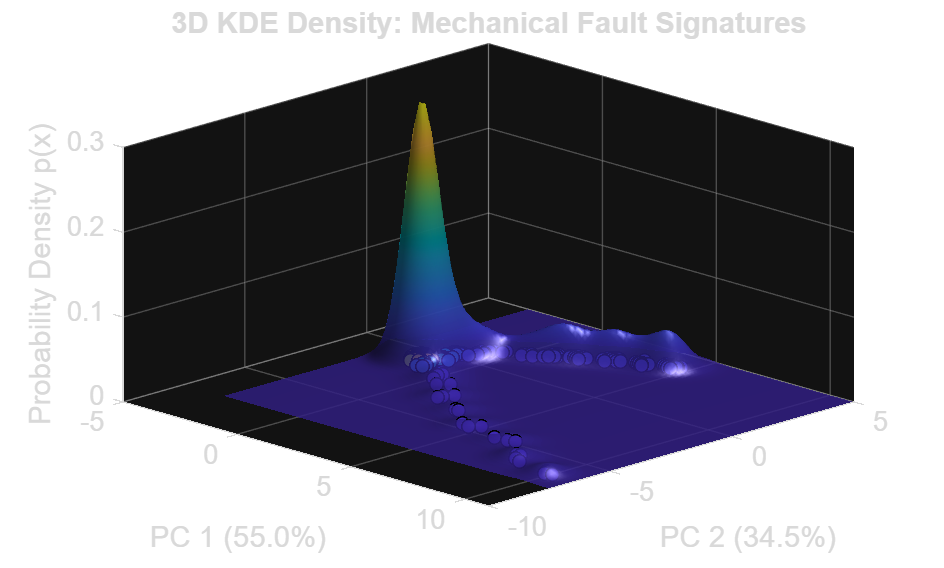

% Load the 14-dimensional feature set
df = readtable('pump_features.csv');

% Standardize and reduce to 2D via PCA
X = df{:, 1:14};
X_scaled = zscore(X);
[~, score, ~, ~, explained] = pca(X_scaled);
X_2d = score(:, 1:2);

% Generate grid for PDF evaluation
x_range = linspace(min(X_2d(:,1))-1, max(X_2d(:,1))+1, 100);
y_range = linspace(min(X_2d(:,2))-1, max(X_2d(:,2))+1, 100);
[X_grid, Y_grid] = meshgrid(x_range, y_range);
grid_pts = [X_grid(:), Y_grid(:)];

% Fit and Evaluate Kernel Density Estimation (KDE)
% mvksdensity replaces fitgmdist and pdf. bw acts as the smoothing parameter (h).
bw = 0.5; 
Z_vec = mvksdensity(X_2d, grid_pts, 'Bandwidth', bw);
Z = reshape(Z_vec, size(X_grid));

% Plotting
figure('Color', 'w');

% Surface colored by density height (Z) instead of discrete grid_labels
surf(X_grid, Y_grid, Z, Z, 'EdgeColor', 'k', 'EdgeAlpha', 0.1, 'FaceAlpha', 0.8);
hold on;

% Project original data points to the Z=0 plane
% Points colored by their individual density evaluation
point_densities = mvksdensity(X_2d, X_2d, 'Bandwidth', bw);
scatter3(X_2d(:,1), X_2d(:,2), zeros(size(X_2d,1),1), 25, point_densities, 'filled', 'MarkerEdgeColor', 'k');

% Aesthetics and Depth
colormap(parula); 
view(45, 30);
grid on;
title('3D KDE Density: Mechanical Fault Signatures');
xlabel(sprintf('PC 1 (%.1f%%)', explained(1)));
ylabel(sprintf('PC 2 (%.1f%%)', explained(2)));
zlabel('Probability Density p(x)');
shading interp;
camlight; lighting gouraud;